# Convolution due to uncertanty  on motion

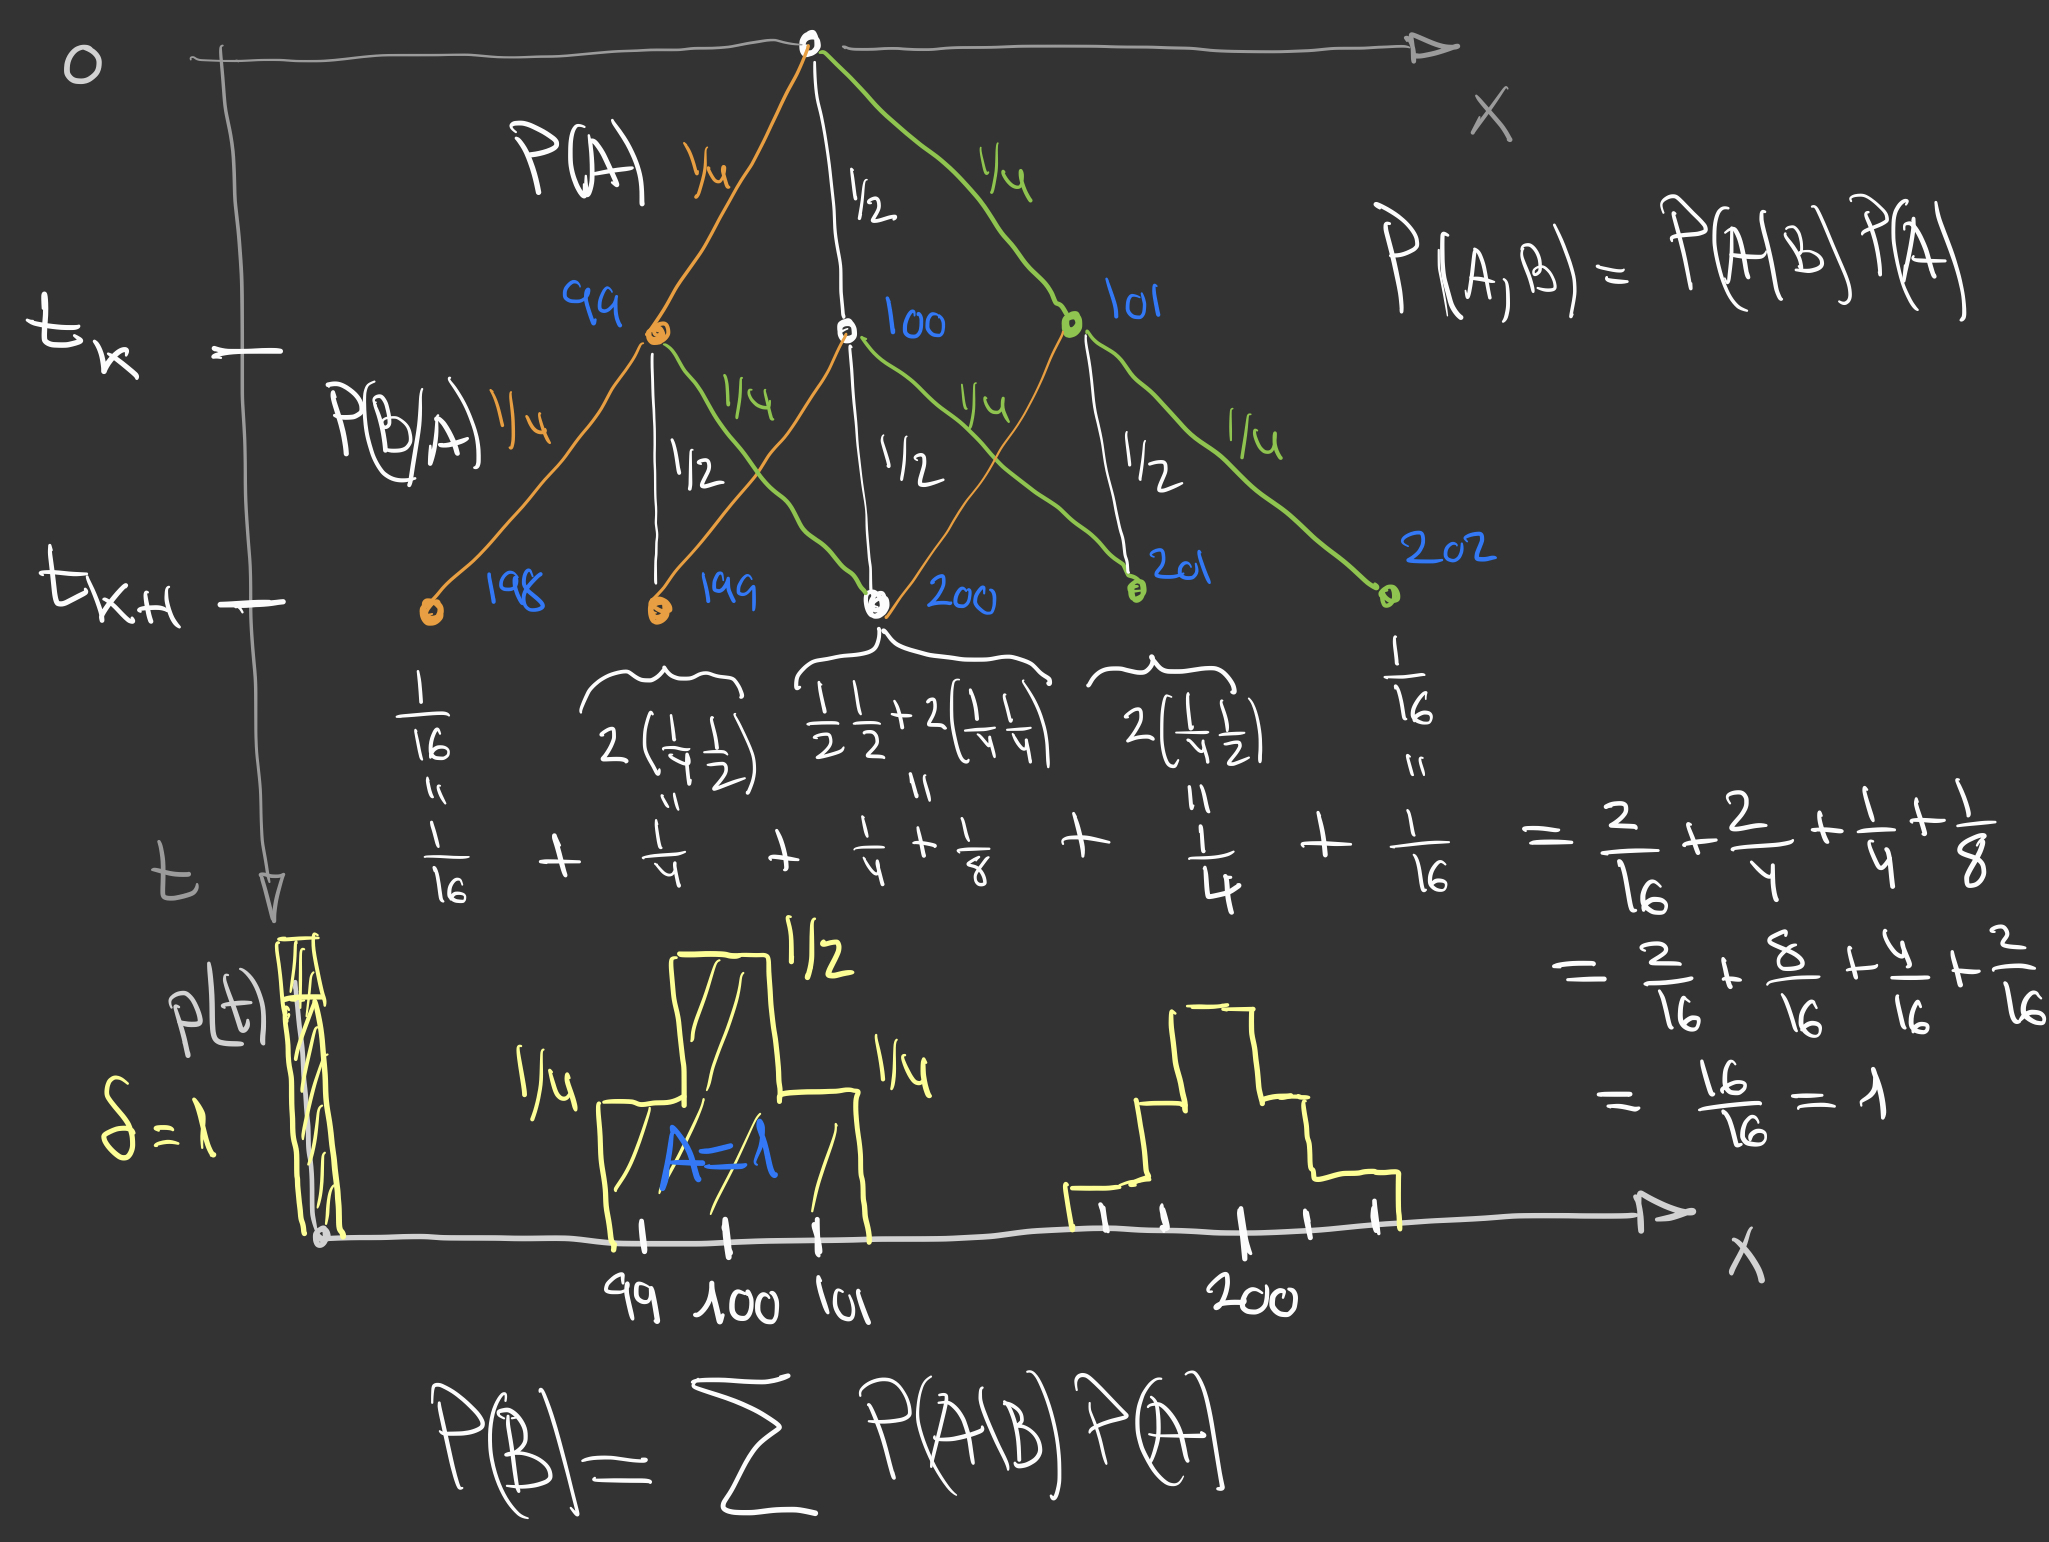

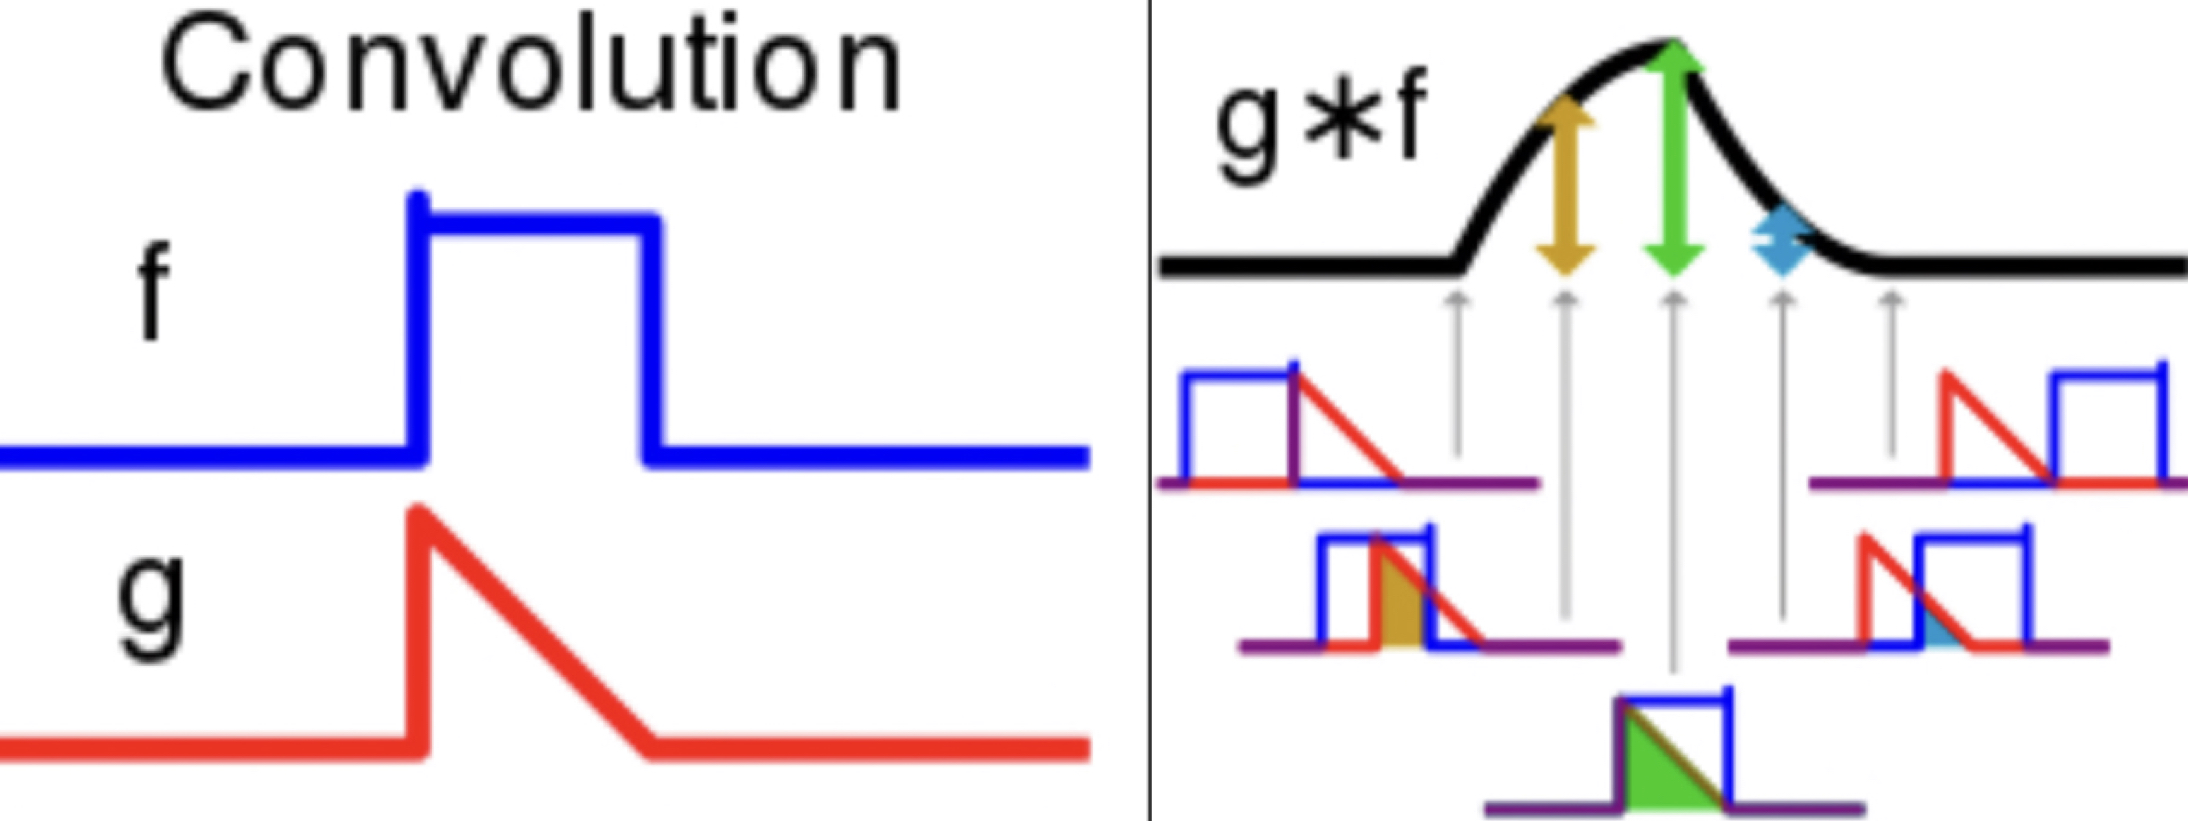

See an animation:

[https://es.wikipedia.org/wiki/Convolución#/media/Archivo:Convolucion_Funcion_Pi.gif](https://es.wikipedia.org/wiki/Convolución#/media/Archivo:Convolucion_Funcion_Pi.gif)

Visit:

https://es.mathworks.com/help/matlab/ref/conv.html

## Initial position and probability to be there

ini_pose=0

ini_pose = 0

s_d=0.0001 %0.1 mm

s_d = 1.0000e-04

p_ini_pose=1/(2*s_d/3)% probability ini pose

p_ini_pose = 15000

## Motion uncertanty and first motion

Uncertanty

u=[0.25 0.5 0.25]

u =     0.2500    0.5000    0.2500


First motion

conv_1=conv(u,p_ini_pose)/p_ini_pose

conv_1 =     0.2500    0.5000    0.2500


cp1=cumsum(conv_1,2)

cp1 =     0.2500    0.7500    1.0000


pt1=cp1(length (cp1))

pt1 = 1

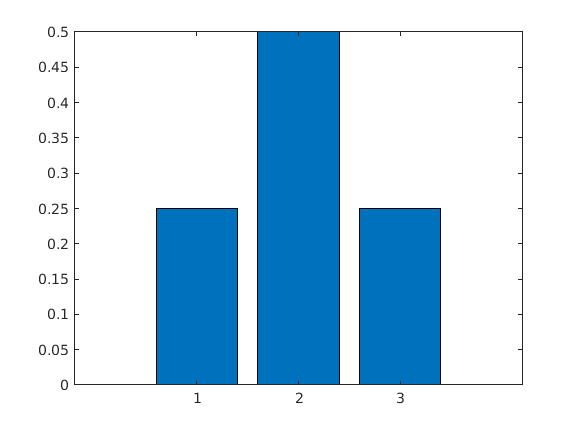

bar(conv_1)

Second motion

conv_2hm=[1/16 1/4 (1/4 +1/8) 1/4 1/16]

conv_2hm =     0.0625    0.2500    0.3750    0.2500    0.0625


conv_2=conv(u,conv_1)

conv_2 =     0.0625    0.2500    0.3750    0.2500    0.0625


cp2=cumsum(conv_2,2)

cp2 =     0.0625    0.3125    0.6875    0.9375    1.0000


pt2=cp2(length (cp2))

pt2 = 1

Third motion

conv_3=conv(u,conv_2)

conv_3 =     0.0156    0.0938    0.2344    0.3125    0.2344    0.0938    0.0156


cp3=cumsum(conv_3,2)

cp3 =     0.0156    0.1094    0.3438    0.6562    0.8906    0.9844    1.0000


pt3=cp3(length (cp3))

pt3 = 1

Four motion

conv_4=conv(u,conv_3)

conv_4 =     0.0039    0.0312    0.1094    0.2188    0.2734    0.2188    0.1094    0.0312    0.0039


cp4=cumsum(conv_4,2)

cp4 =     0.0039    0.0352    0.1445    0.3633    0.6367    0.8555    0.9648    0.9961    1.0000


pt4=cp4(length (cp4))

pt4 = 1

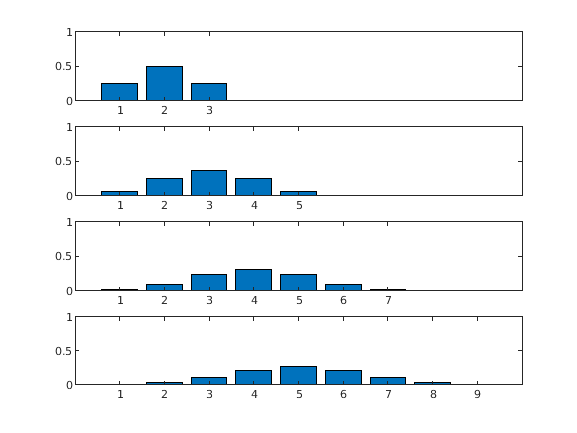

subplot(411)
bar(conv_1)
axis([0 10 0 1])
subplot(412)
bar(conv_2)
axis([0 10 0 1])
subplot(413)
bar(conv_3)
axis([0 10 0 1])
subplot(414)
bar(conv_4)
axis([0 10 0 1])

x=[-2:1:10]

x =     -2    -1     0     1     2     3     4     5     6     7     8     9    10


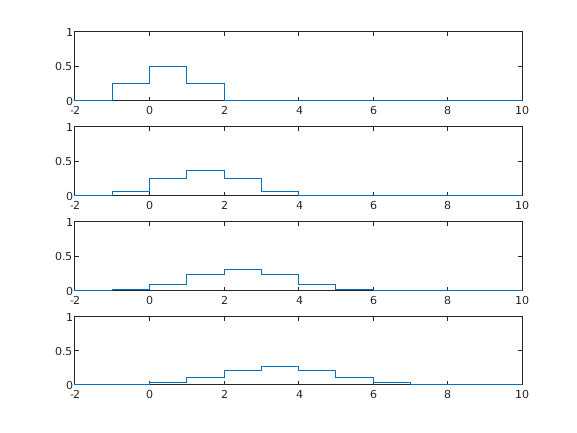

subplot(411)
stairs(x,[0 conv_1 0 0 0 0 0 0 0 0 0])
axis([-2 10 0 1])
subplot(412)
stairs(x,[0 conv_2 0 0 0 0 0 0 0])
axis([-2 10 0 1])
subplot(413)
stairs(x,[0 conv_3 0 0 0 0 0])
axis([-2 10 0 1])
subplot(414)
stairs(x,[0 conv_4 0 0 0])
axis([-2 10 0 1])